clc;clear;
addpath("ccdm\");addpath("Compute_fun\");addpath("mat_data\");

## **初始化一些参数**

设计一个概率成型的编码调制方案，使用LDPC编码，当调制阶数为n = log2(M)时，编码码率为R = n-2/n。

M = 64

M = 64

n = log2(M)

n = 6

M_ASK = 2^(n/2)

M_ASK = 8

R = (n-2)/n

R = 0.6667

nSim = 10000;

QAM由两路ASK信号构成,每路ASK信号独立同分布，根据文件名读取之前保存的分布

filename_bestP = ['best_P_',num2str(2^(n/2)),'ASK.mat'];
load(filename_bestP);
showsnr = 13%滑动滑块可以显示不同信噪比下的最优M-B分布

showsnr = 13

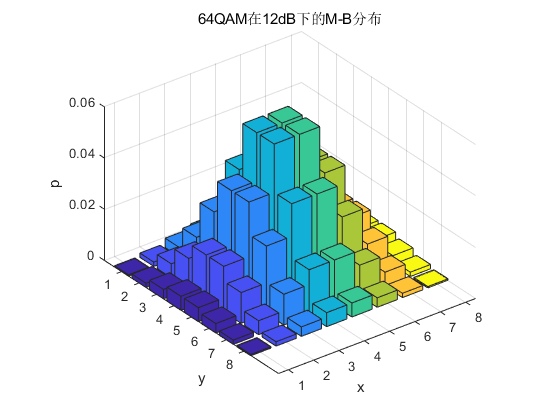

titlestring = [num2str(M),'QAM在',num2str(showsnr-1),'dB下的M-B分布'];
bar3(PX(showsnr,:)'*PX(showsnr,:));xlabel('x');ylabel('y');zlabel('p');title(titlestring)

信道和编码相关的参数

snr = 6:0.5:14;     %信噪比
PX = initialize_PX(snr,M_ASK)

错误使用 save
必须为字符串标量或字符向量。

出错 initialize_PX (line 47)
save(['mat_data/',filename_bestP],snr_Px);

EsN0=10.^(snr/10);
LDPC_bitlength = 1296; %码长可在648，1296   1944，64800中选择

n_ASK = LDPC_bitlength*2/n;  %ASK信号的长度
if LDPC_bitlength == 64800
    H = dvbs2ldpc(R);            %LDPC的H矩阵
else
    H =sparse(buildH( LDPC_bitlength, R));            %LDPC的H矩阵
end

初始化LDPC编解码函数

ldpcEncoder = comm.LDPCEncoder(H);
ldpcDecoder = comm.LDPCDecoder(H);

调制编码相关的一些参数

%ASK正的信号映射表
ASK_map = 1:2:2^(n/2)-1
ASK_Graymap(Graycode(1:length(ASK_map))+1) = ASK_map
Bin2Gray_map(Graycode(1:length(ASK_map))+1) = 1:length(ASK_map);
%LDPC符号里面的比特交织
switch M
    case 16
        bit_map_pi = [1];
        bit_map_pi_Uniform = [2,1]
    case 64
        bit_map_pi = [2,1];
        bit_map_pi_Uniform = [3,2,1];
    case 256
        bit_map_pi = [2,3,1];
        bit_map_pi_Uniform = [3,4,2,1];
end
%格雷映射表（不考虑符号位）
[~,Gray_table] = Graycode([length(ASK_map):-1:1,1:length(ASK_map)]);
ASK = [-ASK_map(end:-1:1),ASK_map]
Gray_table = [zeros(1,length(ASK_map)),ones(1,length(ASK_map));Gray_table']
Gray_table_map_bin = bi2de(Gray_table','left-msb')'
xx = 1:length(Gray_table_map_bin);
Gray_table_map(Gray_table_map_bin+1) = xx

对数似然比的计算公式

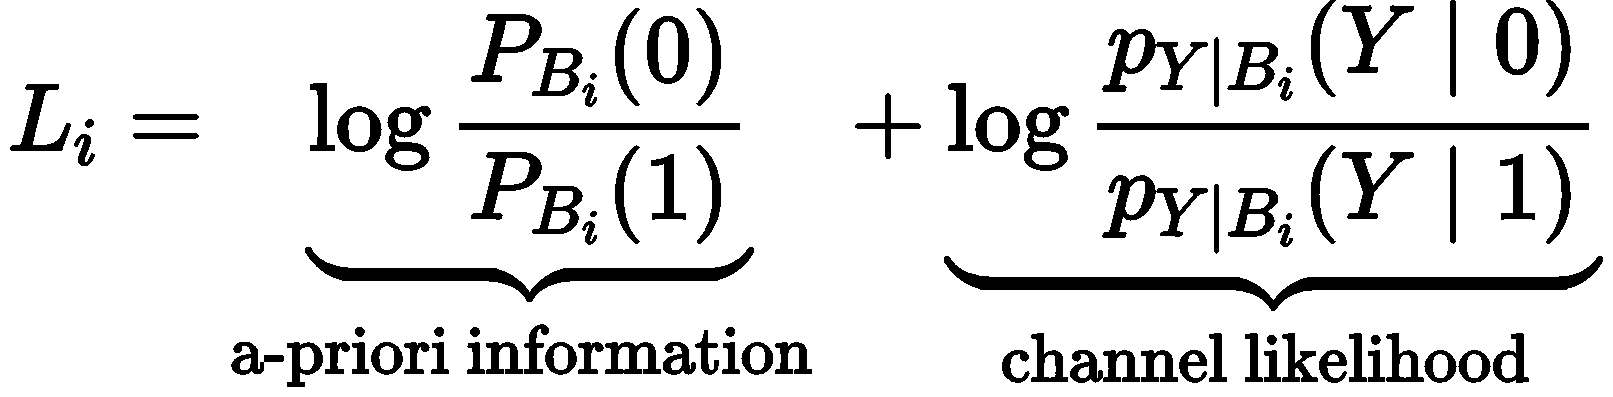

化简后

P = @(y,a,d,px) exp(-(y-a).^2./(2*d^2)) *px';

## **仿真环节**

for ii = 1:length(snr)
    

初始化CCDM, best_P为原始分布，p_quant为CCDM量化后的输出分布，n_ASK为输出符号个数，nBitsInfo为输入比特个数

    best_P = PX(ii,:);
    best_P1 = 2*best_P(length(best_P)/2+1:end);
    [p_quant,nBitsInfo,n_i] = ccdm.initialize(best_P1,n_ASK);
    
    R_CCDM = nBitsInfo/(n_ASK*log2(length(best_P1)));
    
    nerr_bit = 0;
    nerr_bit_Uniform = 0;
    

**发送端部分**

对随机比特分布匹配后，进行格雷映射与交织送入LDPC编码产生冗余位，与正的ASK信号相乘后得到需要的ASK分布

然后讲两路独立的ASK信号分别调制到实部虚部，相加得到方形QAM信号

    for k = 1:nSim
        %信源比特
        txBits_I = randi(2,1,nBitsInfo)-1;
        txBits_Q = randi(2,1,nBitsInfo)-1;
        %不进行概率成型的信源
        txBits_I_Uniform = randi(2,1,R*LDPC_bitlength)'-1;
        txBits_Q_Uniform = randi(2,1,R*LDPC_bitlength)'-1;
        
        
        %I路ASK
        i_TX=ccdm.encode(txBits_I,n_i).'+1;
        %格雷映射
        [~,Graymap_Tx_I_Bit] = Graycode(i_TX);
        %交织映射
        pimap_Tx_I_Bit = Graymap_Tx_I_Bit(:,bit_map_pi);
        %LDPC编码
        data_I_bit = reshape(pimap_Tx_I_Bit',[],1);
        encData_I_bit = ldpcEncoder(data_I_bit);
        sign_symbol_I = encData_I_bit(length(data_I_bit)+1:end)*2-1;
        out_Tx_I = ASK_map(i_TX)'.*sign_symbol_I;
        
        %不进行概率成型
        encData_I_bit_Uniform = reshape(ldpcEncoder(txBits_I_Uniform),n/2,[])';
        %交织
        pimap_Tx_I_Bit_Uniform = encData_I_bit_Uniform(:,bit_map_pi_Uniform);
        %Gray映射
        out_Tx_I_Uniform = ASK(Gray_table_map(bi2de(pimap_Tx_I_Bit_Uniform,'left-msb')+1));
        
        %Q路ASK
        q_TX=ccdm.encode(txBits_Q,n_i).'+1;
        %格雷映射
        [~,Graymap_Tx_Bit_Q] = Graycode(q_TX);
        %交织映射
        pimap_Tx_Q_Bit = Graymap_Tx_Bit_Q(:,bit_map_pi);
        %LDPC编码
        data_Q_bit = reshape(pimap_Tx_Q_Bit',[],1);
        encData_Q_bit = ldpcEncoder(data_Q_bit);
        sign_symbol_Q = encData_Q_bit(length(data_Q_bit)+1:end)*2-1;
        out_Tx_Q = ASK_map(q_TX)'.*sign_symbol_Q;
        
        %不进行概率成型
        encData_Q_bit_Uniform = reshape(ldpcEncoder(txBits_Q_Uniform),n/2,[])';
        pimap_Tx_Q_Bit_Uniform = encData_Q_bit_Uniform(:,bit_map_pi_Uniform);
        %Gray映射
        out_Tx_Q_Uniform = ASK(Gray_table_map(bi2de(pimap_Tx_Q_Bit_Uniform,'left-msb')+1));
        %I路Q路实部虚部叠加就得到了我们需要的QAM信号
        Tx_QAM_PS =  out_Tx_I + 1i.*out_Tx_Q;
        Tx_QAM_Uniform =  out_Tx_I_Uniform + 1i.*out_Tx_Q_Uniform;

**信道部分·**

        %生成噪声 
        Es = mean(abs(Tx_QAM_PS).^2);
        N0=Es./EsN0(ii);
        variance=N0;
        Standard_variance1=sqrt(variance);
        noise=(randn(1,n_ASK).'+1i*randn(1,n_ASK).')./sqrt(2);
        %AWGN
        Rx_QAM = Tx_QAM_PS + Standard_variance1.*noise;
        
        %均匀分布的噪声
        Es_Uniform = mean(abs(Tx_QAM_Uniform).^2);
        N0_Uniform=Es_Uniform./EsN0(ii);
        variance_Uniform=N0_Uniform;
        Standard_variance1_Uniform=sqrt(variance_Uniform);
        noise=(randn(1,n_ASK).'+1i*randn(1,n_ASK).')./sqrt(2);
        %AWGN
        Rx_QAM_Uniform = Tx_QAM_Uniform.' + Standard_variance1_Uniform.*noise;
        


**接收端部分**

        %I路Q路分开处理
        Rx_I = real(Rx_QAM);Rx_Q = imag(Rx_QAM);%PS的
        Rx_I_Uniform = real(Rx_QAM_Uniform);Rx_Q_Uniform = imag(Rx_QAM_Uniform);%均匀分布的
        
        %计算格雷映射下每一个位的对数似然比
        
        for j = 1:n/2
            %I路各比特位LLR
            %PS
            llr_I(:,j) = log(P(Rx_I,ASK(Gray_table(j,:)==0),Standard_variance1,best_P(Gray_table(j,:)==0))./...
                             P(Rx_I,ASK(Gray_table(j,:)==1),Standard_variance1,best_P(Gray_table(j,:)==1)));
            %随机
            llr_I_Uniform(:,j) = log(P(Rx_I_Uniform,ASK(Gray_table(j,:)==0),Standard_variance1_Uniform,ones(1,M_ASK/2)/M_ASK)./...
                                     P(Rx_I_Uniform,ASK(Gray_table(j,:)==1),Standard_variance1_Uniform,ones(1,M_ASK/2)/M_ASK));
            %Q路各比特位LLR
            %PS
            llr_Q(:,j) = log(P(Rx_Q,ASK(Gray_table(j,:)==0),Standard_variance1,best_P(Gray_table(j,:)==0))./...
                             P(Rx_Q,ASK(Gray_table(j,:)==1),Standard_variance1,best_P(Gray_table(j,:)==1)));
            %随机
            llr_Q_Uniform(:,j) = log(P(Rx_Q_Uniform,ASK(Gray_table(j,:)==0),Standard_variance1_Uniform,ones(1,M_ASK/2)/M_ASK)./...
                                     P(Rx_Q_Uniform,ASK(Gray_table(j,:)==1),Standard_variance1_Uniform,ones(1,M_ASK/2)/M_ASK));
        end
        
        
        %PS
        %I路处理
        llr_I_other = llr_I(:,1);   %符号位LLR
        llr_I_info = llr_I(:,2:end);%编码位LLR
        %交织映射
        llr_I_info_pidemap = llr_I_info(:,bit_map_pi)';
        llr_I_ldpc = [llr_I_info_pidemap(:);llr_I_other];
        %译码
        Rx_decodData_I_bit = ldpcDecoder(llr_I_ldpc);
        Rx_decodData_I_bit = reshape(Rx_decodData_I_bit,n/2-1,[])';
        %解交织
        Rx_pimap_I_Bit(:,bit_map_pi) = Rx_decodData_I_bit;
        %逆映射
        i_RX = Bin2Gray_map(bi2de(Rx_pimap_I_Bit,'left-msb')+1)';
        %CCDM解码
        rxBits_I = ccdm.decode(i_RX-1,n_i,nBitsInfo);
        
        %随机分布
        %解交织映射
        llr_I_info_pidemap_Uniform = llr_I_Uniform(:,bit_map_pi_Uniform)';
        llr_I_ldpc_Uniform = llr_I_info_pidemap_Uniform(:);
        %译码
        rxBits_I_Uniform = ldpcDecoder(llr_I_ldpc_Uniform);
        
        
        %Q路处理
        llr_Q_other = llr_Q(:,1);   %符号位LLR
        llr_Q_info = llr_Q(:,2:end);%编码位LLR
        %交织映射
        llr_Q_info_pimap = llr_Q_info(:,bit_map_pi)';
        llr_Q_ldpc = [llr_Q_info_pimap(:);llr_Q_other];
        %译码
        Rx_decodData_Q_bit = ldpcDecoder(llr_Q_ldpc);
        Rx_decodData_Q_bit = reshape(Rx_decodData_Q_bit,n/2-1,[])';
        %解交织
        Rx_pimap_Q_Bit(:,bit_map_pi) = Rx_decodData_Q_bit;
        %逆映射
        Q_RX = Bin2Gray_map(bi2de(Rx_pimap_Q_Bit,'left-msb')+1)';
        %CCDM解码
        rxBits_Q = ccdm.decode(Q_RX-1,n_i,nBitsInfo);
        
        %随机分布
        %解交织映射
        llr_Q_info_pidemap_Uniform = llr_Q_Uniform(:,bit_map_pi_Uniform)';
        llr_Q_ldpc_Uniform = llr_Q_info_pidemap_Uniform(:);
        %译码
        rxBits_Q_Uniform = ldpcDecoder(llr_Q_ldpc_Uniform);
        
        %统计误比特率
        %PS
        nerr_bit =  nerr_bit + sum(rxBits_I~=txBits_I) + sum(rxBits_Q~=txBits_Q);
        %随机
        nerr_bit_Uniform =  nerr_bit_Uniform + sum(rxBits_I_Uniform~=txBits_I_Uniform) + sum(rxBits_Q_Uniform~=txBits_Q_Uniform);
    end
    biterr_rate(ii) = nerr_bit/(nBitsInfo*nSim*2)
    biterr_rate_Uniform(ii) = nerr_bit_Uniform/(R*LDPC_bitlength*nSim*2)
    
    if ii == 15
            
            scatterplot(Rx_QAM);
            title('PS在snr=15dB的星座图')
            
            scatterplot(Rx_QAM_Uniform)
            title('均匀分布在snr=15dB的星座图')
    end
end

figure()
semilogy(snr,biterr_rate);hold on
semilogy(snr,biterr_rate_Uniform);
legend('PS','随机分布');
hold off